# Riepilogo 03: calcolo dell'incertezza di misura data la pdf o la popolazione degli errori

## 1 - Calcoli per pdf di errore non simmetrica

Le quantità richieste sono calcolate a partire dalla conoscenza di una popolazione di errori.

Le stesse quantità possono essere calcolate a partire dalla conoscenza di pdf, cdf, icdf.

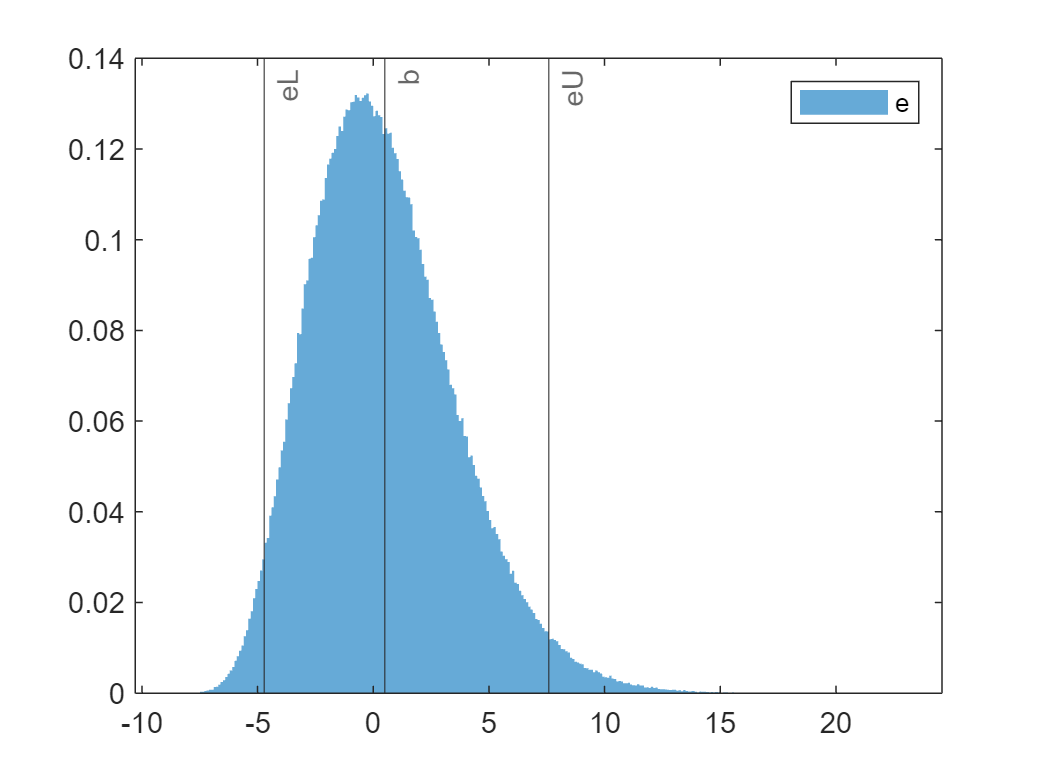

% Nota:
% Gli intervalli richiesti, del tipo:
% Prob(e in [eL,eU]) = cp
% Prob(eb in [ebL,ebU]) = cp
% sono sempre "a code uguali"

% Dati
% y = popolazione di valori misurati (vettore riga)
% x = popolazione di valori veri (vettore riga)
% cp = probabilità di copertura

% Domande
% e = popolazione di errori di misura (vettore riga)
% b = bias della misura
% U = incertezza di caso peggiore (WCU) 
% eL = limite inferiore ("lower") dell'intervallo in cui cade e con prob. cp 
% eU = limite superiore ("upper") dell'intervallo in cui cade e con prob. cp
%
% yb = popolazione di valori misurati, dopo correzione del bias
% eb = popolazione di errori di misura, dopo correzione del bias
% Ub = incertezza di caso peggiore (WCU) per la misura dopo correzione del bias
% ebL = limite inferiore ("lower") dell'intervallo a code uguali in cui e1 cade con prob. cp 
% ebU = limite superiore ("upper") dell'intervallo a code uguali in cui e1 cade con prob. cp


% Codice iniziale
clear
rng('default') % per ripetibilità dei risultati
n = 10; mu1 = 1; % parametri della pdf
Nsim = 1e6;
e = gamrnd(n,mu1,[1,Nsim]);
e = e - mean(e) + 0.5;
x = unifrnd(0,10,[1,Nsim]);
y = x + e;
cp = 0.95;

### Soluzione

e = y-x

e =     7.0605    3.1002   -3.3582    1.2691   13.0034   -0.0305   -0.4592    5.5750    5.2738   -3.1250    6.1703    3.7512   -0.7489   -2.0828   -2.9816   -2.1405    5.3614   -1.9981   -4.2404   -0.5672    1.1699    0.0710    2.2501    4.0395    0.4067   -2.9010    5.7552    1.3654    4.0710    0.2658    4.0058    0.4338   -1.9649    9.4683    2.6816    3.1986   -3.5730    1.7629   -0.4327    1.0994    5.9885    2.4959   -0.5739   -3.0264    0.4939   10.6369    0.7584   -4.6863   -4.4109   -2.3423


b = mean(e)

b = 0.5000

U = max(abs(e)) % WCU: è poco significativa se la pdf ha una o entrambe le code "lunghe"

U = 22.9704

eL = quantile(e,(1-cp)/2)

eL = -4.7100

eU = quantile(e,(1+cp)/2)

eU = 7.5822

In generale, la misura corretta dal bias è


$$y_b =y-b$$


yb = y - b

yb =     8.0612   12.0675    5.2764    8.6040   16.4576    8.6054    6.1463    7.4508   14.6666    2.5833   12.4898   13.1429    2.1516   -0.6881    1.8611   -0.9438   10.0871    4.4328   -0.2278    0.6165    5.7528    3.0112   10.5886    7.1968    7.0305    4.0573   13.7727    9.1451    7.4303    6.3921   10.0702    6.5251    1.4460   14.0873    9.9235   10.6941    0.6422    9.2721    7.5298    8.9288   12.4332    8.7461    4.4349   -1.0050    4.3631   16.4872    7.1060    2.0277    1.7144    5.5311


eb = yb - x

eb =     6.5605    2.6002   -3.8582    0.7691   12.5034   -0.5305   -0.9592    5.0750    4.7738   -3.6250    5.6703    3.2512   -1.2489   -2.5828   -3.4816   -2.6405    4.8614   -2.4981   -4.7404   -1.0672    0.6699   -0.4290    1.7501    3.5395   -0.0933   -3.4010    5.2552    0.8654    3.5710   -0.2342    3.5058   -0.0662   -2.4649    8.9683    2.1816    2.6986   -4.0730    1.2629   -0.9327    0.5994    5.4885    1.9959   -1.0739   -3.5264   -0.0061   10.1369    0.2584   -5.1863   -4.9109   -2.8423



$$e_b =y_b -x=\left(y-b\right)-x=e-b$$


eb = e - b % equivalente

eb =     6.5605    2.6002   -3.8582    0.7691   12.5034   -0.5305   -0.9592    5.0750    4.7738   -3.6250    5.6703    3.2512   -1.2489   -2.5828   -3.4816   -2.6405    4.8614   -2.4981   -4.7404   -1.0672    0.6699   -0.4290    1.7501    3.5395   -0.0933   -3.4010    5.2552    0.8654    3.5710   -0.2342    3.5058   -0.0662   -2.4649    8.9683    2.1816    2.6986   -4.0730    1.2629   -0.9327    0.5994    5.4885    1.9959   -1.0739   -3.5264   -0.0061   10.1369    0.2584   -5.1863   -4.9109   -2.8423



$$E\left\lbrack e_b \right\rbrack =E\left\lbrack e-b\right\rbrack =E\left\lbrack e\right\rbrack -b=b-b=0$$


% Verifica della correzione del bias (non richiesta dalla traccia):
mean(eb) % deve essere zero

ans = 1.5348e-16

Ub = max(abs(eb)) % WCU: è poco significativa se la pdf ha una o entrambe le code "lunghe"

Ub = 22.4704

ebL = quantile(eb,(1-cp)/2)

ebL = -5.2100

ebU = quantile(eb,(1+cp)/2)

ebU = 7.0822

Modo alternativo di calcolare Ub, ebL, ebU:

poiché abbiamo eb = e - b, ovviamente si ha:

Ub = U - abs(b)

Ub = 22.4704

ebL = eL - b

ebL = -5.2100

ebU = eU - b

ebU = 7.0822

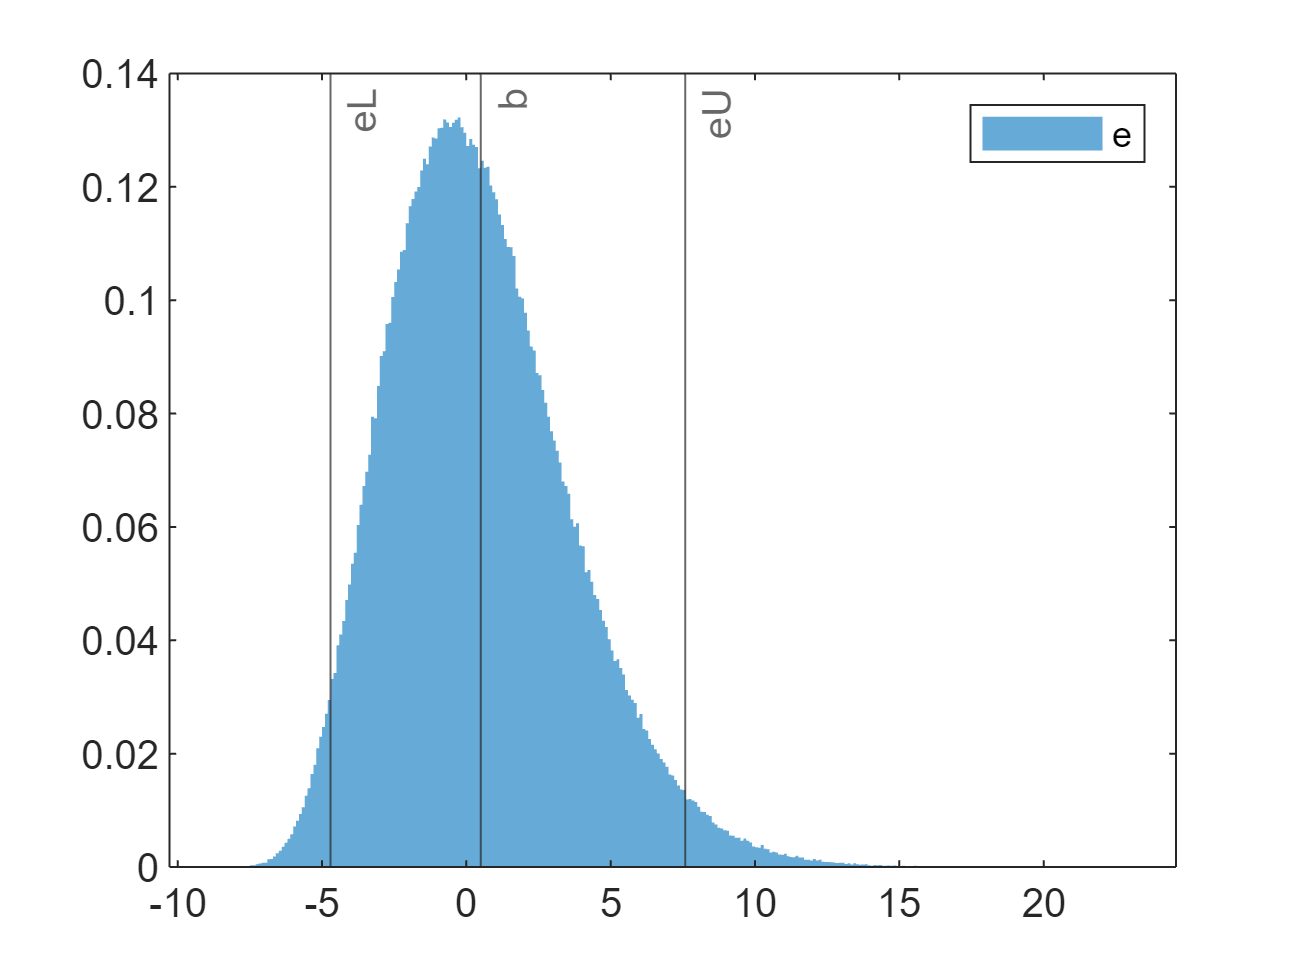

% Grafico nella traccia
histogram(e,'Normalization','pdf','EdgeColor','none')
xline(b,'-','b')
xline(eL,'-','eL')
xline(eU,'-','eU')
legend('e')

## 2 - Calcoli per pdf di errore simmetrica (nota la popolazione)

Le quantità richieste sono calcolate a partire dalla conoscenza di  una popolazione di errori.

Le stesse quantità possono essere calcolate a partire dalla conoscenza di pdf, cdf, icdf.

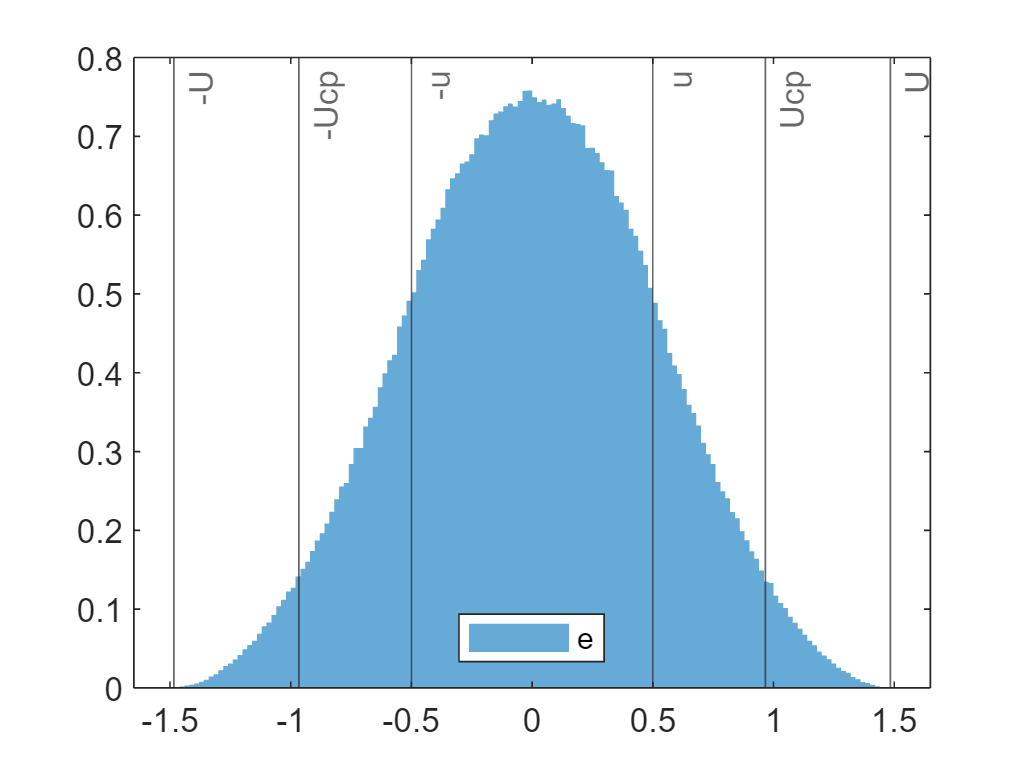

% Si suppone che la pdf dell'errore sia simmetrica attorno allo zero 
% (funzione pari)

% Dati
% e = popolazione di valori di errore di misura (vettore riga)
% cp = probabilità di copertura

% Domande
% U = incertezza di caso peggiore (WCU)
% Ucp = incertezza estesa con probabilità di copertura cp
% e1L = limite inferiore ("lower") dell'intervallo a code uguali in cui e cade con prob. cp
% e1U = limite superiore ("upper") dell'intervallo a code uguali in cui e cade con prob. cp
% u = incertezza standard

% Codice iniziale
clear
rng('default') % per ripetibilità dei risultati
Nsim = 1e6;
e = unifrnd(-0.5,0.5,1,Nsim) + unifrnd(-0.5,0.5,1,Nsim) +unifrnd(-0.5,0.5,1,Nsim);
cp = 0.95;

### Soluzione

U = max(abs(e))

U = 1.4839

Ucp = quantile(e,(1+cp)/2) % UE per pdf simmetrica

Ucp = 0.9659

ebU = Ucp % per definizione

ebU = 0.9659

ebL = -Ucp % per l'ipotesi di simmetria

ebL = -0.9659

ebL = quantile(e,(1-cp)/2) % alternativa

ebL = -0.9692


$$u=\mathrm{std}\left\lbrack e\right\rbrack =\sqrt{E\left\lbrack {\left(e-b\right)}^2 \right\rbrack }=\sqrt{E\left\lbrack e^2 \right\rbrack \;}$$


u = sqrt(mean(e.^2))

u = 0.4997

u = std(e) % alternativa, con divisione per N-1 invece che per N

u = 0.4997

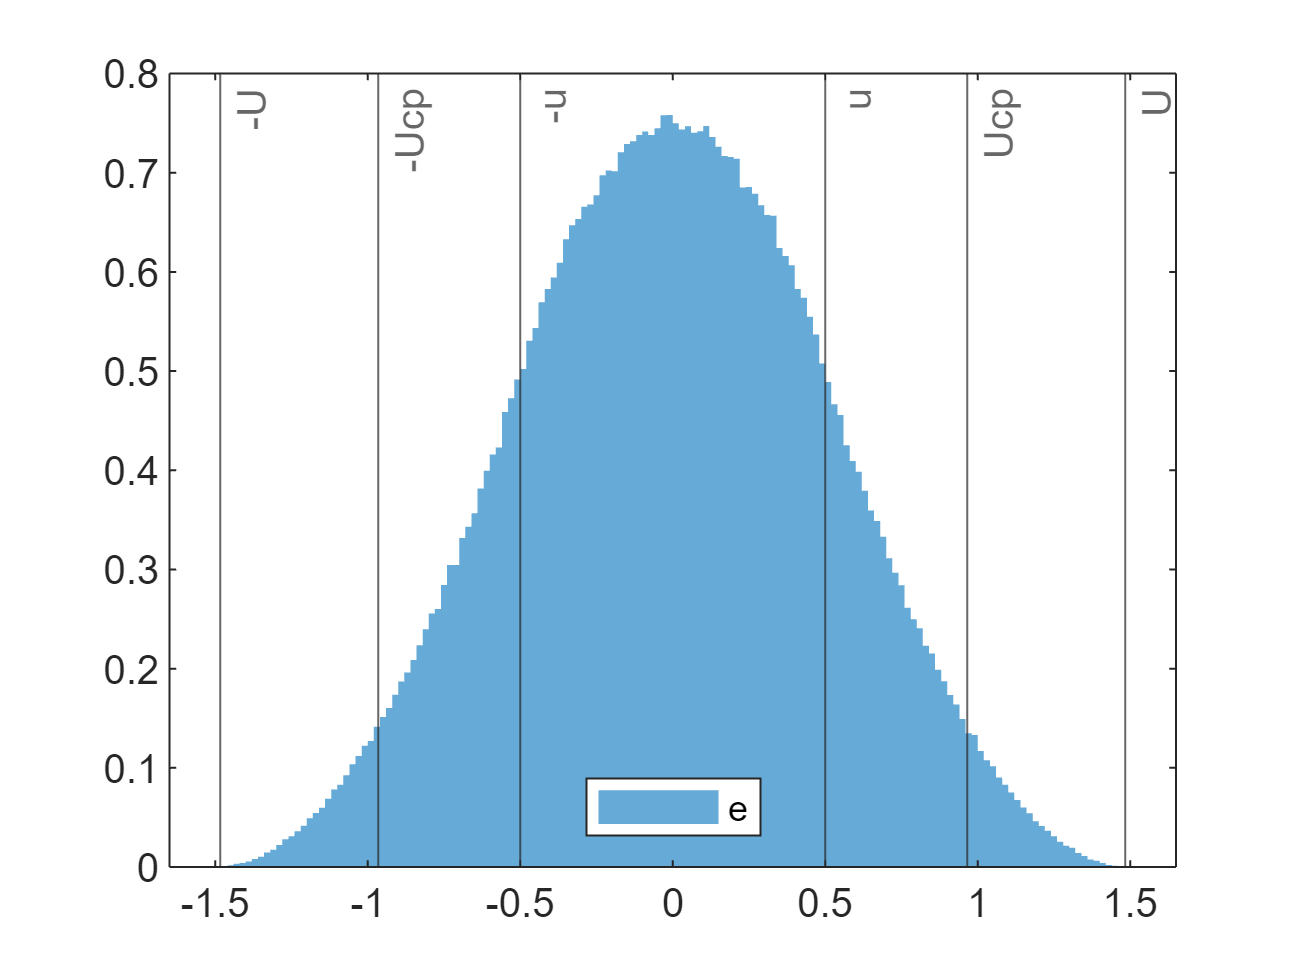

% Grafico nella traccia
histogram(e,'Normalization','pdf','EdgeColor','none')
xline(u,'-','u')
xline(-u,'-','-u')
xline(Ucp,'-','Ucp')
xline(-Ucp,'-','-Ucp')
xline(U,'-','U')
xline(-U,'-','-U')
legend('e','location','south')

## 3 - Calcoli per pdf di errore gaussiana

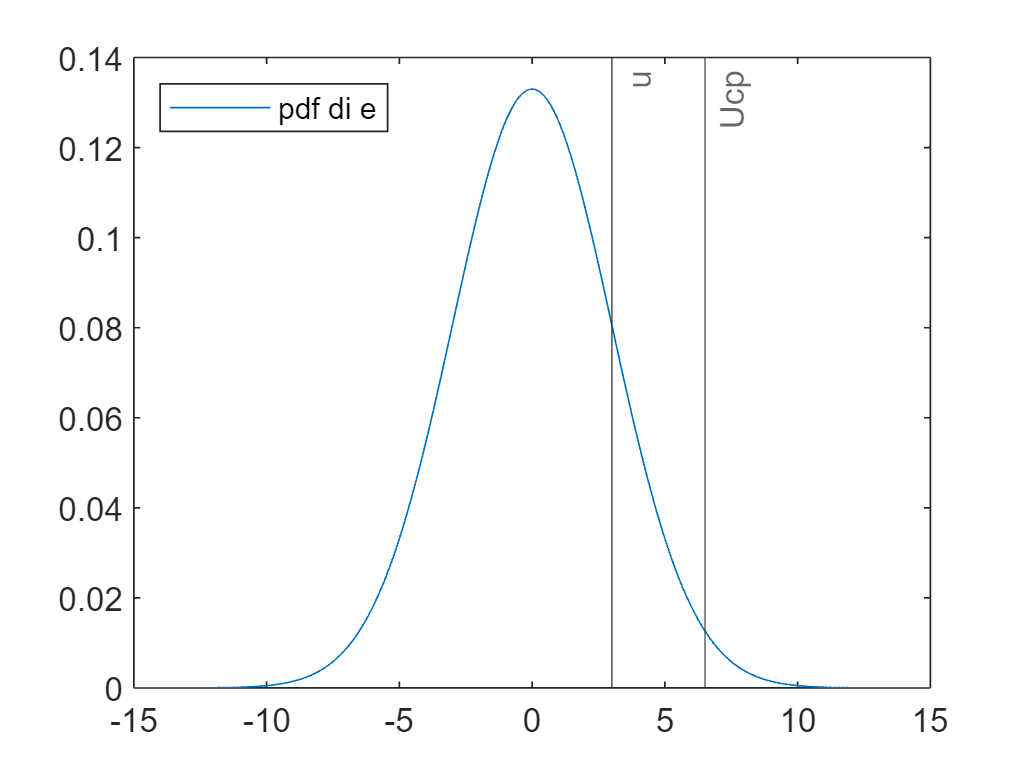

% Sappiamo che la pdf dell'errore è gaussiana a media nulla.

% Dati
% cp0 = probabilità di copertura assegnata
% k1 = fattore di copertura assegnato
% u = incertezza standard

% Domande
% U = incertezza di caso peggiore (WCU)
% kmax = massimo fattore di copertura applicabile
%
% k0 = fattore di copertura associato a cp0
% Ucp0 = incertezza estesa con probabilità di copertura cp0
%
% cp1 = probabilità di copertura associata a k1
% Ucp1 = incertezza estesa con probabilità di copertura cp1
%
% k90 = fattore di copertura per cp = 0.90, scritto con due decimali
% k95 = fattore di copertura per cp = 0.95, scritto con due decimali
%
% cp2 = probabilità di copertura per k = 2, scritta con quattro decimali
% cp3 = probabilità di copertura per k = 3, scritta con quattro decimali


% Codice iniziale
clear
cp0 = 0.97;
k1 = 2.5;
u = 3;

### Soluzione

U = +inf % per errore gaussiano, la WCU è infinita

U = Inf

kmax = +inf % kmax = U/u = infinito. Si può applicare qualsiasi fattore di copertura 

kmax = Inf

Quantità associate a cp0


$$k=\Phi {\;}^{-1} \left(\frac{1+cp}{2}\right)$$



$$U_{cp} =k\cdot u$$


cp0 % inserito solo per visualizzare il valore

cp0 = 0.9700

k0 = norminv((1+cp0)/2) % da cp a k

k0 = 2.1701

Ucp0 = k0*u

Ucp0 = 6.5103


$$cp=2\Phi \left(k\right)-1$$


k1 % inserito solo per visualizzare il valore

k1 = 2.5000

cp1 = 2*normcdf(k1) - 1 % da k a cp

cp1 = 0.9876

Ucp1 = k1*u

Ucp1 = 7.5000

k90 = 1.64 % cp = 0.90

k90 = 1.6400

k95 = 1.96 % cp = 0.95

k95 = 1.9600

k90 = round(norminv((1+0.9)/2),2) % anche valida

k90 = 1.6400

k95 = round(norminv((1+0.95)/2),2) % anche valida

k95 = 1.9600

cp2 = 0.9545 % k = 2

cp2 = 0.9545

cp3 = 0.9973 % k = 3

cp3 = 0.9973

cp2 = round(2*normcdf(2)-1,4) % anche valida

cp2 = 0.9545

cp3 = round(2*normcdf(3)-1,4) % anche valida

cp3 = 0.9973

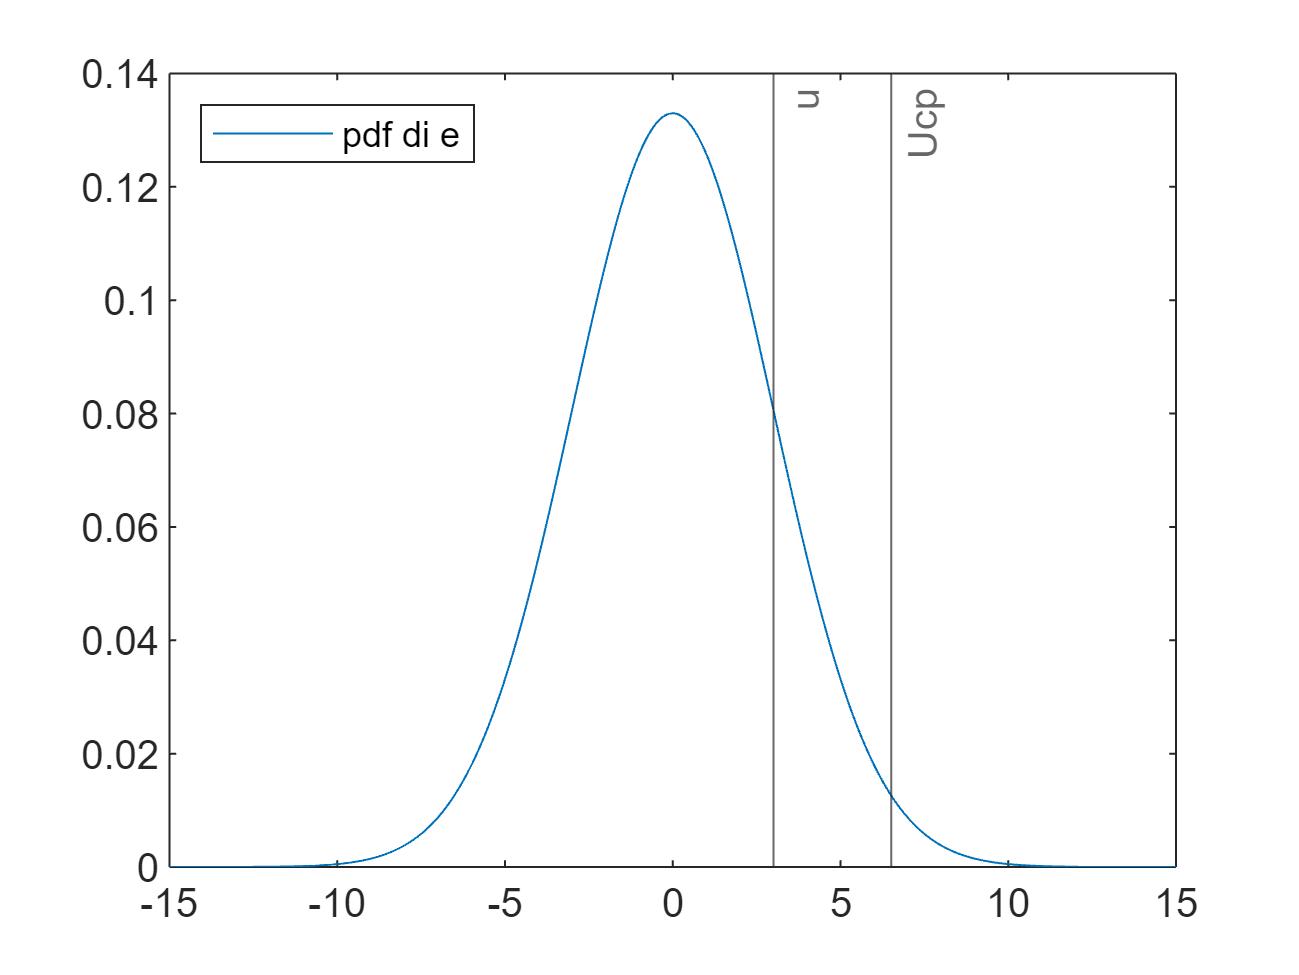

% Grafico per la traccia
x = linspace(-15,15,1001);
f = normpdf(x,0,u);
plot(x,f)
xline(u,'-','u')
xline(Ucp0,'-','Ucp')
legend('pdf di e','Location','nw')

## 4 - Calcoli per pdf di errore simmetriche non gaussiane (nota la pdf)

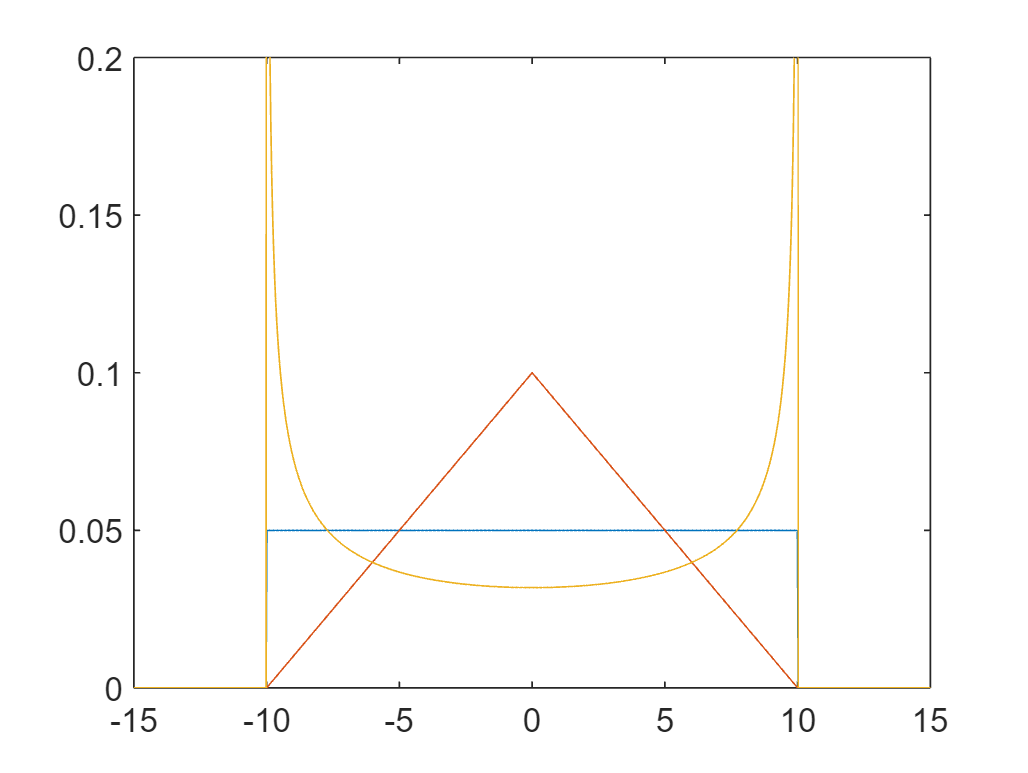

% Nota l'incertezza di caso peggiore, si richiedono incertezza standard e 
% fattore di copertura massimo per una pdf di errore simmetrica, 
% nei seguenti casi:
% 1 - uniforme
% 2 - triangolare
% 3 - arcoseno
% 4 - a campana, convoluzione di 3 pdf uniformi uguali 
% 5 - a campana, convoluzione di N pdf uniformi uguali, con N>3

% Dati 
% U = incertezza di caso peggiore
% N = parametro per il caso 5

% Domande
% u1 = incertezza standard pdf 1
% u2 = incertezza standard pdf 2
% u3 = incertezza standard pdf 3
% u4 = incertezza standard pdf 4
% u5 = incertezza standard pdf 5
% kmax1 = max fattore di copertura applicabile pdf 1
% kmax2 = max fattore di copertura applicabile pdf 2
% kmax3 = max fattore di copertura applicabile pdf 3
% kmax4 = max fattore di copertura applicabile pdf 4
% kmax5 = max fattore di copertura applicabile pdf 5
% Ucp1 = incertezza estesa con cp = 95%, pdf 1
% Ucp2 = incertezza estesa con cp = 95%, pdf 2
% Ucp3 = incertezza estesa con cp = 95%, pdf 3
% Ucp4 = incertezza estesa con cp = 95%, pdf 4
% Ucp5 = incertezza estesa con cp = 95%, pdf 5

% Nota:
% Per calcolare l'incertezza estesa Ucp con cp = 95%, 
% applicare l'approssimazione gaussiana quando ciò è possibile; 
% altrimenti, approssimarla con la WCU

% Codice iniziale
U = 10;
N = 5;

Nel caso di convoluzione di $N$ rettangoli uguali, si ha

$U_0 =\frac{U}{N}$ WCU per ciascuna pdf rettangolare

$u_0 =\frac{U_0 }{\sqrt{3}}=\frac{U}{N\sqrt{3}}$ SU per ciascuna pdf rettangolare

$u^2 =N\;u_0^2 =N\;\frac{U^2 }{{3N}^2 }=\frac{U}{3N}$ SU al quadrato per la pdf finale


$$u=\frac{U}{\sqrt{3N}}$$


u1 = U/sqrt(3) % pdf rettangolare

u1 = 5.7735

u2 = U/sqrt(6) % pdf triangolare

u2 = 4.0825

u3 = U/sqrt(2) % pdf arcoseno

u3 = 7.0711

u4 = U/3 % pdf a campana, convoluzione di 3 rettangoli uguali

u4 = 3.3333

u5 = U/sqrt(3*N) % pdf a campana, convoluzione di N rettangoli uguali

u5 = 2.5820


$$k_{\max } =\frac{U}{u}$$


kmax1 = sqrt(3) % U/u1

kmax1 = 1.7321

kmax2 = sqrt(6) % U/u2

kmax2 = 2.4495

kmax3 = sqrt(2) 

kmax3 = 1.4142

kmax4 = 3

kmax4 = 3

kmax5 = 3*N

kmax5 = 15

k = norminv((1+0.95)/2) % fattore di copertura per l'approx gaussiana

k = 1.9600

Ucp1 = U % uniforme: approx. gaussiana non applicabile

Ucp1 = 10

Ucp2 = k*u2 % triangolare: approx. gaussiana applicabile

Ucp2 = 8.0015

Ucp3 = U % arcoseno: approx. gaussiana non applicabile

Ucp3 = 10

Ucp4 = k*u4 % approx. gaussiana applicabile

Ucp4 = 6.5332

Ucp5 = k*u5 % approx. gaussiana applicabile

Ucp5 = 5.0606

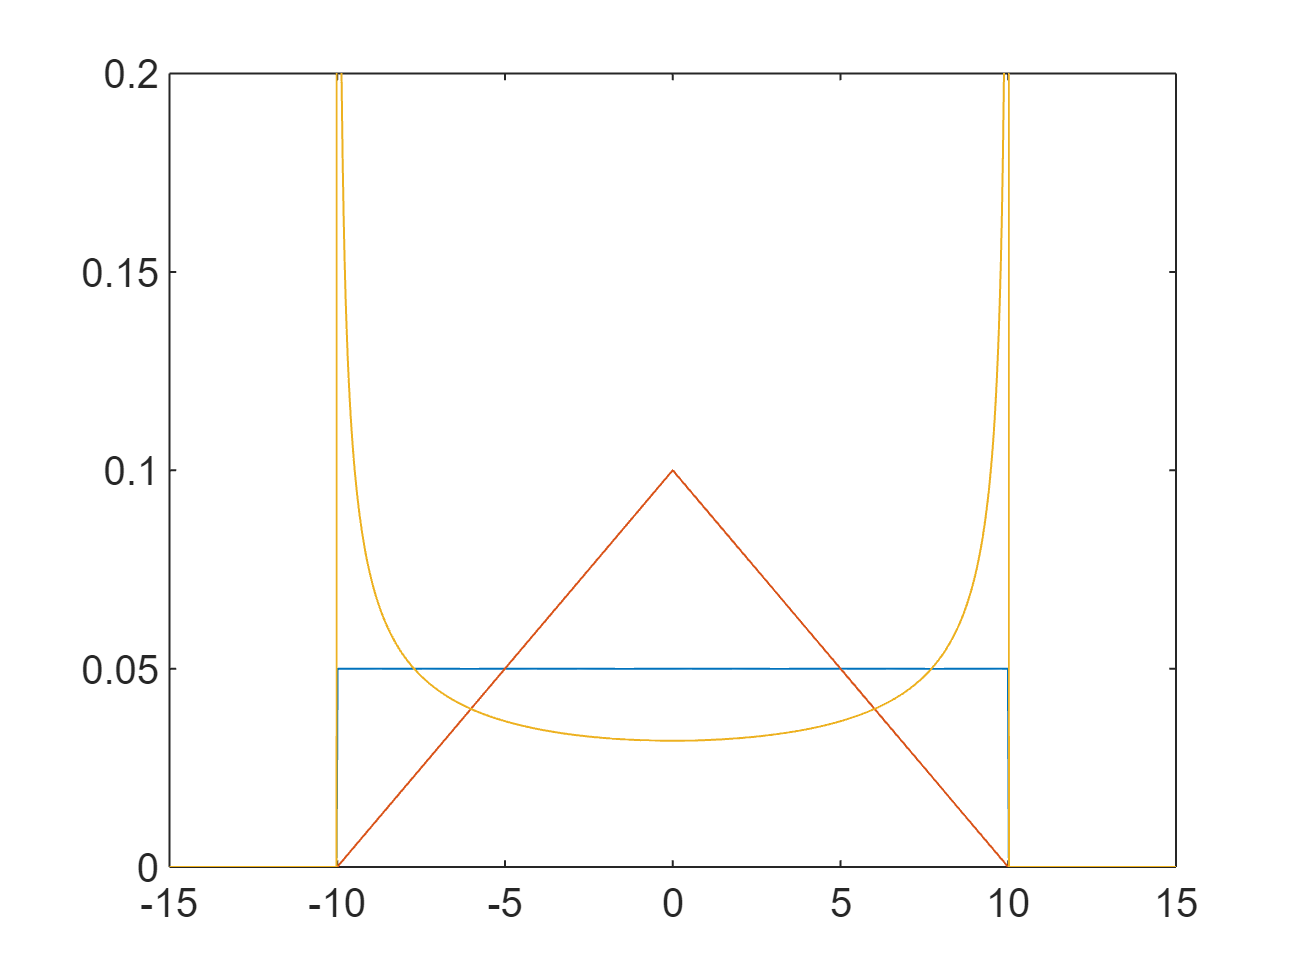

% Grafico per figura
x = linspace(-1.5*U,1.5*U,1001);
f1 = unifpdf(x,-U,U);
f2 = tripuls(x/(2*U))/U;
f3 = 1/pi./sqrt(1 - (x/U).^2)/U;
f3(not(imag(f3)==0)) = 0;
plot(x,f1,x,f2,x,f3)
ylim([0,2/U])